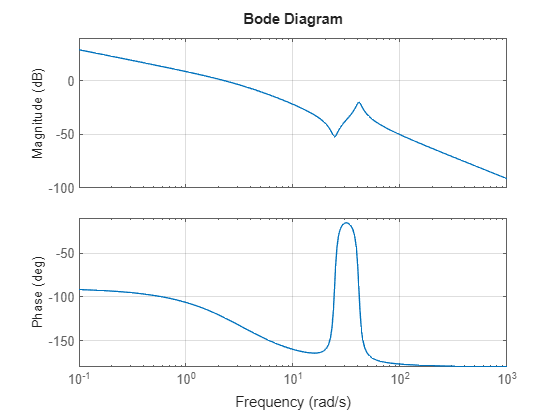


delta = log(1/Mp)/sqrt(pi^2 + log(1/Mp)^2);
wg = 3/(delta*ts_5);
phi = atan(2*delta/(sqrt(sqrt(1+4*(delta^4))-2*(delta^2))))*rad2deg;
step_amplitude = 1;

% u -> theta

s = tf('s');
Dp = lab3.Jeq*beam.Jb*s^3 + (lab3.Jeq*beam.Bb+beam.Jb*lab3.Beq)*s^2 + (lab3.Beq*beam.Bb + joint.k*(lab3.Jeq + beam.Jb/(gbox.N^2)))*s + joint.k*(lab3.Beq + beam.Bb/(gbox.N^2));
P = drv.dcgain*mot.Kt*(beam.Jb*s^2 + beam.Bb*s + joint.k)/((gbox.N*s)*((sens.curr.Rs+mot.R)*Dp + mot.Kt*mot.Ke*(beam.Jb*s^2 + beam.Bb*s + joint.k)));
figure;
bode(P)
grid on


[magPwg, phasePwg] = bode(P, wg)

magPwg = 0.0831

phasePwg = -159.7282

dK = abs(magPwg)^-1;
dPh = -pi + phi*deg2rad - phasePwg*deg2rad;


## PID

a = 4;

kp = dK * cos(dPh);
Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*wg);
Ti = a*Td;
kd = kp*Td;
ki = kp/Ti;
tl = 1/(10*wg);
fprintf("PID: kp = %d, Kd = %d, ki = %d, tl = %d",kp,kd,ki,tl);

PID: kp = 1.139446e+01, Kd = 8.071364e-01, ki = 4.021428e+01, tl = 1.013929e-02